[cbAudio1, cbFs1] = audioread('common_blackbird.wav');
% convert cbAudio to mono
cbAudio1 = sum(cbAudio1, 2) / size(cbAudio1, 2);
[cbAudio2, cbFs2] = audioread('common_blackbird_2.wav');
cbAudio2 = sum(cbAudio2, 2) / size(cbAudio2, 2);

sound(cbAudio1,cbFs1)

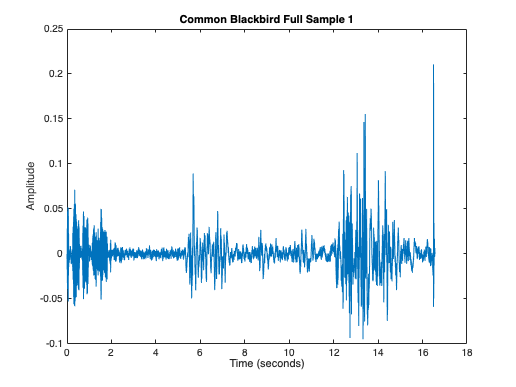

plot((0:numel(cbAudio1)-1)/cbFs1,cbAudio1)
title('Common Blackbird Full Sample 1')
xlabel('Time (seconds)')
ylabel('Amplitude')

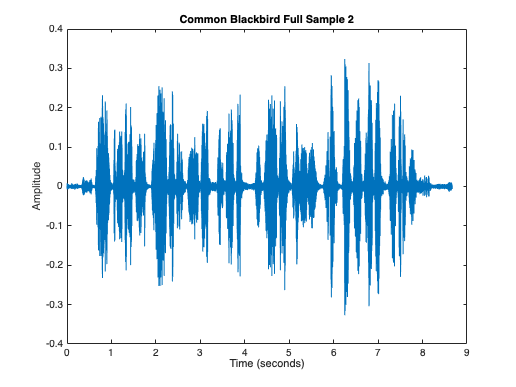

plot((0:numel(cbAudio2)-1)/cbFs2,cbAudio2)
title('Common Blackbird Full Sample 2')
xlabel('Time (seconds)')
ylabel('Amplitude')

cb1 = normalize(cbAudio1(1:1+2*cbFs1))/8;
cb2 = normalize(cbAudio2(1:1+2*cbFs2))/8;

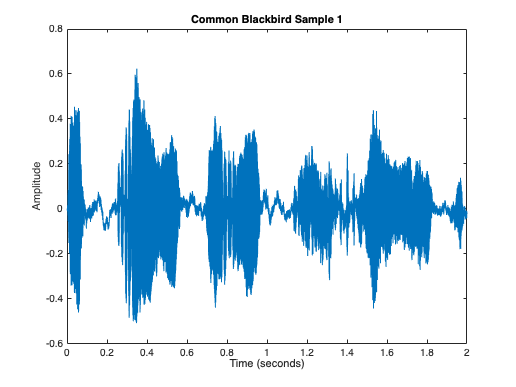

plot((0:numel(cb1)-1)/cbFs1,cb1)
title('Common Blackbird Sample 1')
xlabel('Time (seconds)')
ylabel('Amplitude')

sound(cb1,cbFs1);

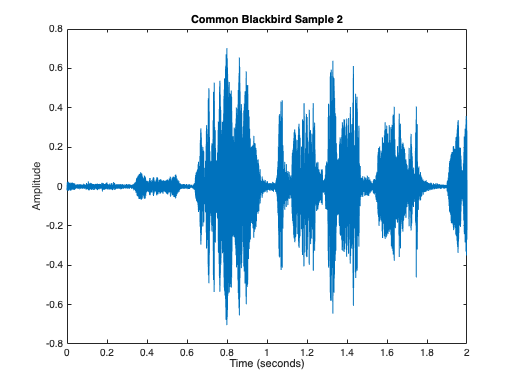

plot((0:numel(cb2)-1)/cbFs2,cb2)
title('Common Blackbird Sample 2')
xlabel('Time (seconds)')
ylabel('Amplitude')

sound(cb2,cbFs2);

gammaFiltBank = gammatoneFilterBank([50 20000],64,cbFs1);
gammaFiltBank2 = gammatoneFilterBank([50 20000],64,cbFs2);

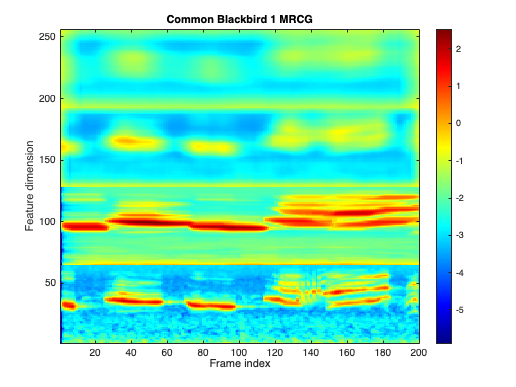

cbAudioOut1 = gammaFiltBank(cb1);
mrcgFeats = mrcg(cbAudioOut1, cbFs1);
imagesc(mrcgFeats)
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Common Blackbird 1 MRCG')
set(gca,'YDir','normal')

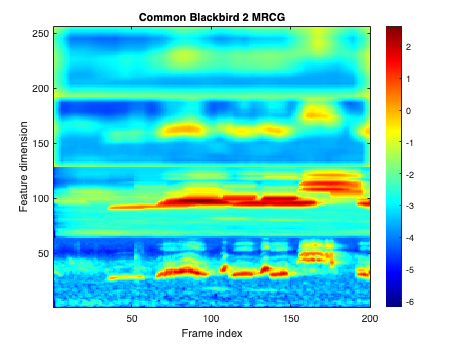

cbAudioOut2 = gammaFiltBank2(cb2);
cbMrcgFeatures2 = mrcg(cbAudioOut2, cbFs2);
imagesc(cbMrcgFeatures2)
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Common Blackbird 2 MRCG')
set(gca,'YDir','normal')

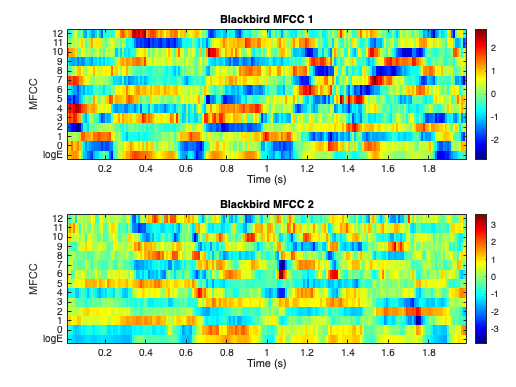

tiledlayout(2,1);

nexttile
mfcc(cb1,cbFs1)
title('Blackbird MFCC 1')

nexttile
mfcc(cb2,cbFs2)
title('Blackbird MFCC 2')

**Adding noise**

[urbanNoise, noiseFs] = audioread('urban_noise_1.wav');
urbanNoise = sum(urbanNoise, 2) / size(urbanNoise, 2);

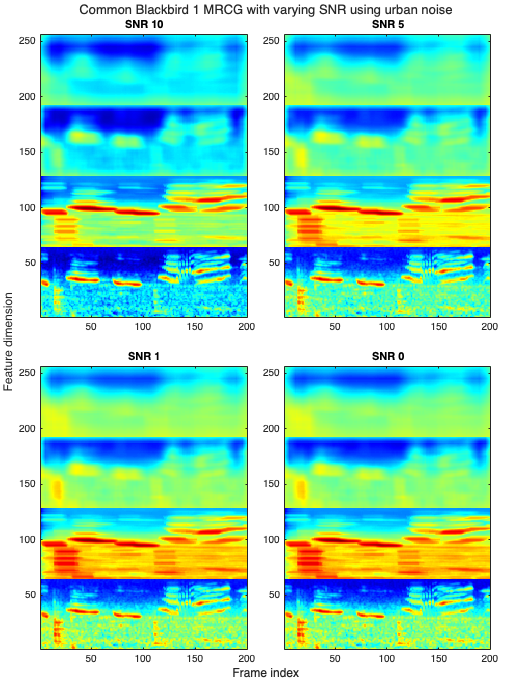

figure('Position', [1,1,600,800])
t = tiledlayout(2,2,'TileSpacing','Compact','Padding','Compact');
for snr = [10, 5, 1, 0]
    noisySig = addNoise(cb1,urbanNoise,snr);
    nexttile
    audioOut = gammaFiltBank(noisySig);
    mrcgFeats = mrcg(audioOut, cbFs1);
    imagesc(mrcgFeats)
    colormap jet
    % colorbar
    ylabel(t, 'Feature dimension')
    xlabel(t, 'Frame index')
    title(sprintf('SNR %d', snr))
    title(t, 'Common Blackbird 1 MRCG with varying SNR using urban noise')
    set(gca,'YDir','normal')
end

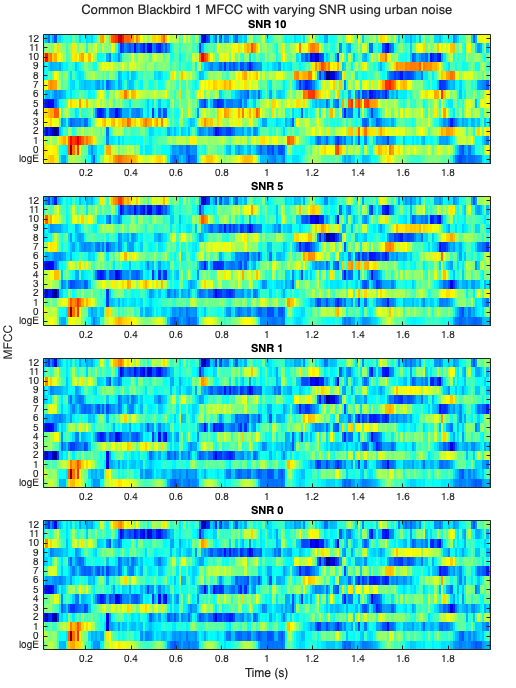

figure('Position', [1,1,600,800])
t = tiledlayout(4,1,'TileSpacing','Compact','Padding','Compact');
for snr = [10, 5, 1, 0]
    noisySig = addNoise(cb1,urbanNoise,snr);
    nexttile
    mfcc(noisySig,cbFs1)
    xlabel('')
    ylabel('')
    colorbar off
    ylabel(t, 'MFCC')
    xlabel(t, 'Time (s)')
    title(sprintf('SNR %d', snr))
    title(t, 'Common Blackbird 1 MFCC with varying SNR using urban noise')
end

[rainforestNoise, rainforestNoiseFs] = audioread('rainforest_noise_1.wav');
rainforestNoise = sum(rainforestNoise, 2) / size(rainforestNoise, 2);

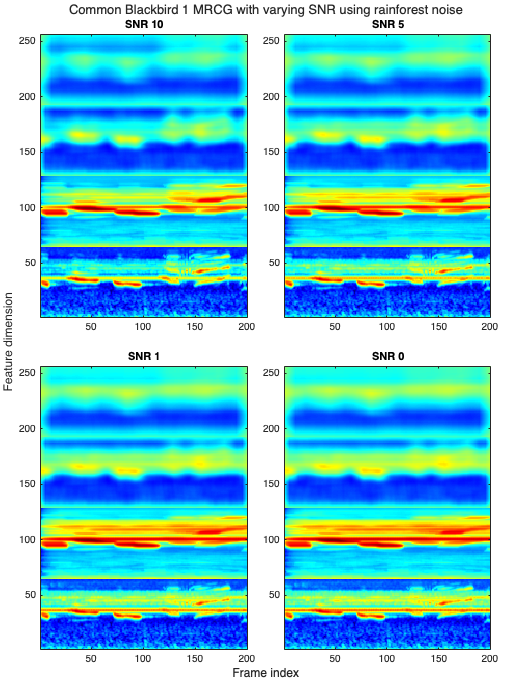

figure('Position', [1,1,600,800])
t = tiledlayout(2,2,'TileSpacing','Compact','Padding','Compact');
for snr = [10, 5, 1, 0]
    noisySig = addNoise(cb1,rainforestNoise,snr);
    nexttile
    audioOut = gammaFiltBank(noisySig);
    mrcgFeats = mrcg(audioOut, cbFs1);
    imagesc(mrcgFeats)
    colormap jet
    % colorbar
    ylabel(t, 'Feature dimension')
    xlabel(t, 'Frame index')
    title(sprintf('SNR %d', snr))
    title(t, 'Common Blackbird 1 MRCG with varying SNR using rainforest noise')
    set(gca,'YDir','normal')
end

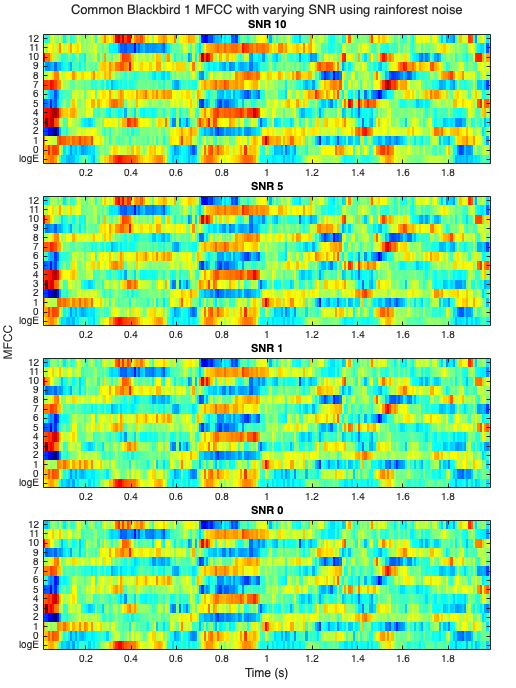

figure('Position', [1,1,600,800])
t = tiledlayout(4,1,'TileSpacing','Compact','Padding','Compact');
for snr = [10, 5, 1, 0]
    noisySig = addNoise(cb1,rainforestNoise,snr);
    nexttile
    mfcc(noisySig,cbFs1)
    xlabel('')
    ylabel('')
    colorbar off
    ylabel(t, 'MFCC')
    xlabel(t, 'Time (s)')
    title(sprintf('SNR %d', snr))
    title(t, 'Common Blackbird 1 MFCC with varying SNR using rainforest noise')
end